**Random Pathing**

We are to test paths randomly according to a set amount of points we must reach

First, let's read the file

openfile = fopen('Distance.txt'); 
%file opening and stuff to be used in textscan
fileData = textscan(openfile,'%s%f%f', 'headerlines',1);
%basically the same as textread
fclose(openfile);
[location,w_dist,n_dist] = fileData{:};
%put output into separate arrays
location_endl = strcat(location', '\n');
%this adds linebreaks to each cell so it displays better
%later on for an output

**An Array of Distances**

Now, to make things faster, we'll be creating an array of distances from each point to the next in the format of dist(n,m) = distance from point n to m. I have a function that uses distance formula (pythagorean theorem) to find distances.

startLoc = 1;
endLoc = 2;
distArray = zeros(15);
%an array of all distances, this does it for forward order
while(endLoc < 16)
    distArray(startLoc,endLoc) = distance2D(n_dist(startLoc),n_dist(endLoc),w_dist(startLoc),w_dist(endLoc));
    if(endLoc == 15)%this works as endLoc won't reach 16 until startLoc == 15
        startLoc = startLoc + 1;
        endLoc = startLoc;
    end %if for next row
    endLoc = endLoc + 1;
end %while
%and this does it in reverse order
startLoc = 15;
endLoc = 14;
while(endLoc > 0)
    distArray(startLoc,endLoc) = distance2D(n_dist(startLoc),n_dist(endLoc),w_dist(startLoc),w_dist(endLoc));
    if(endLoc == 1)%this works as endLoc won't reach 1 until startLoc == 2
        startLoc = startLoc - 1;
        endLoc = startLoc;
    end %if for next row
    endLoc = endLoc - 1;
end %while

**Running paths**

So, now we ask the user for some input on how many paths to run. This part of the code also calculates the distance of a random route based on the array created before and stores the route with the shortest distance.

runs = input('How many paths should be calculated? ');
%asks for input, see command window to enter an input
shortest_dist = inf(1);
%makes sure something will be shorter when tested
for run_num = 1:runs
    path = randperm(14) + 1;
    %resets total
    %makes random path
    step = 2;
    %this variable is to see which step of the path we are on
    total_dist = distArray(1,path(1));
    %this is the first step, and is also why step starts at 2
    while(step < 15)
        total_dist = total_dist + distArray(path(step),path(step-1));
        step = step + 1;
    end %while for total distance
    total_dist = total_dist + distArray(path(14),1);
    %returns to start
    if(total_dist < shortest_dist)
        shortest_dist = total_dist;
        shortest_path = [1,path,1];
        %constructs shortest path into a single array
    end %if for shortest path
    clear total_dist;
end %for simulations

**Output and Mapping**

Now, with our shortest path and distance, we can plot and map this out to a more user friendly display.

fprintf(['The shortest path calculated in ', num2str(runs), ' \nrandom paths is ', num2str(shortest_dist), ' miles']);

The shortest path calculated in 1000000 
random paths is 459.85 miles

%prints shortest milage
fprintf(['This path goes through (in order)\n', location_endl{shortest_path}]);

This path goes through (in order)
Erewhon
Arko
Wedyenoh
Elppa
Brabuhr
Apenequ
Yrrech
Ananab
Nakoyi
Iwik
Nomel
Gif
Mulp
Etad
Onepalaj
Erewhon


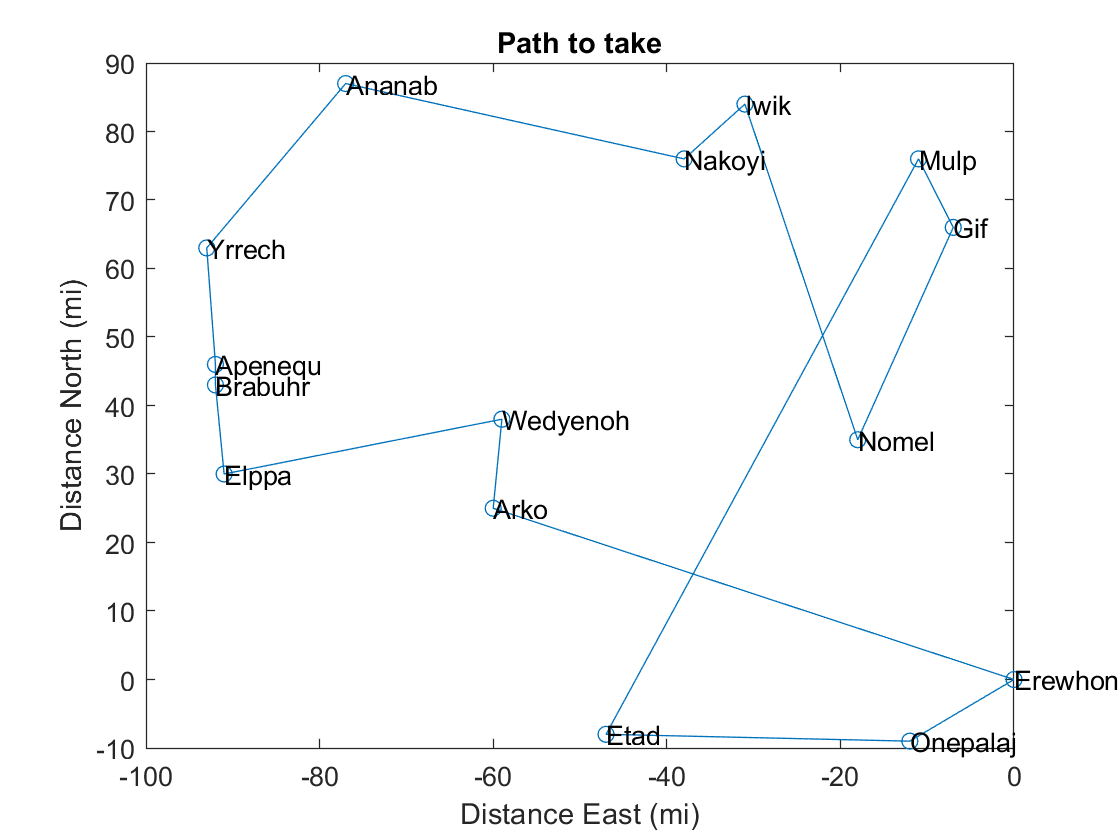

%prints path taken
plot(-w_dist(shortest_path),n_dist(shortest_path),'-o');
%makes plot, note the west distance is negative 
%as we usually think of east to be right
title('Path to take');
xlabel('Distance East (mi)');
ylabel('Distance North (mi)');
text(-w_dist(:),n_dist(:),cellstr(location));

%titles plot and axes, the last one is for labelling